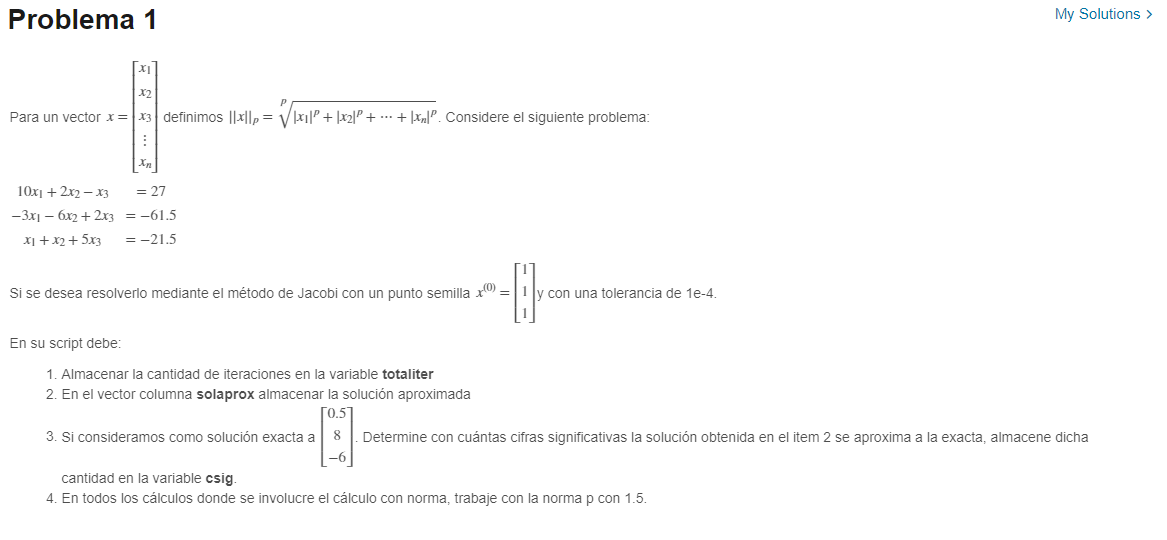

clear
clc

X0 = [1 1 1]';
tol = 1e-4;

A = [10 2 -1; -3 -6 2; 1 1 5];
b = [27; -61.5; -21.5];

z = jacobi_1(A,b,X0,tol)

z =    1.000000000000000   1.000000000000000   1.000000000000000                   0
   2.600000000000000  10.083333333333334  -4.700000000000000   1.000000000000000
   0.213333333333333   7.383333333333333  -6.836666666666667   2.000000000000000
   0.539666666666667   7.864444444444445  -5.819333333333333   3.000000000000000
   0.545177777777778   8.040388888888888  -5.980822222222223   4.000000000000000
   0.493840000000000   7.983803703703703  -6.017113333333333   5.000000000000000
   0.501527925925926   7.997375555555556  -5.995528740740740   6.000000000000000
   0.500972014814815   8.000726456790122  -5.999780696296297   7.000000000000000
   0.499876639012346   7.999587093827160  -6.000339694320987   8.000000000000000
   0.500048611802469   7.999948449053498  -5.999892746567902   9.000000000000000



totaliter = z(end,end)

totaliter =      9


solaprox = (z(end,1:end-1))'

solaprox =    0.500048611802469
   7.999948449053498
  -5.999892746567902



X0 = solaprox;
X1 = [0.5; 8; -6];
err = normaP(X1-X0)/normaP(X1)

err =      1.326254211514338e-05


i = 0;

tope = 5*10^-i;
while err < tope
    i = i +1;
    tope = 5*10^-i;
end
csig = i-1

csig =      5


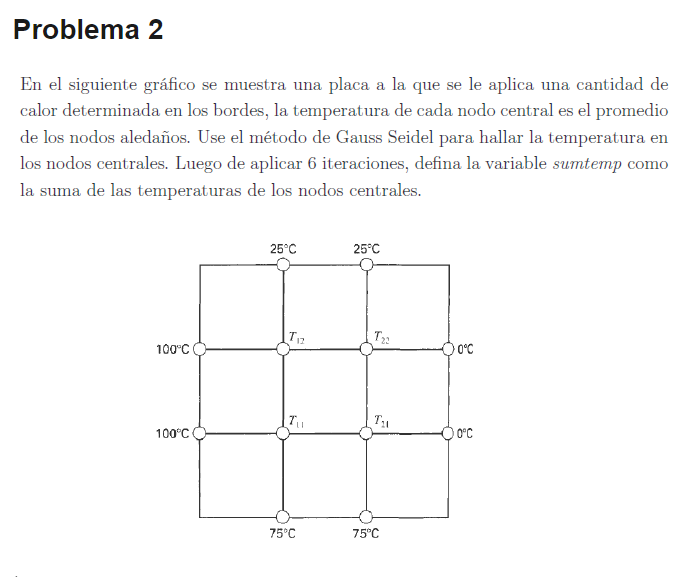

A = [-1 4 0 -1
    0 -1 -1 4
    4 -1 -1 0
    -1 0 4 -1];

A = [4 -1 -1 0
    -1 4 0 -1
    -1 0 4 -1
    0 -1 -1 4]

A =      4    -1    -1     0
    -1     4     0    -1
    -1     0     4    -1
     0    -1    -1     4



A = [4,-1,-1,0;-1,4,0,-1;-1,0,4,-1;0,-1,-1,4]

A =      4    -1    -1     0
    -1     4     0    -1
    -1     0     4    -1
     0    -1    -1     4



b = [175 125 25 75]'

b =    175
   125
    25
    75



n = 6;

X0 = [0 0 0 0]';
z = gausseidel_n(A,b,X0, n);
sumtemp = sum(z(end,1:end))

sumtemp =      1.999290466308594e+02


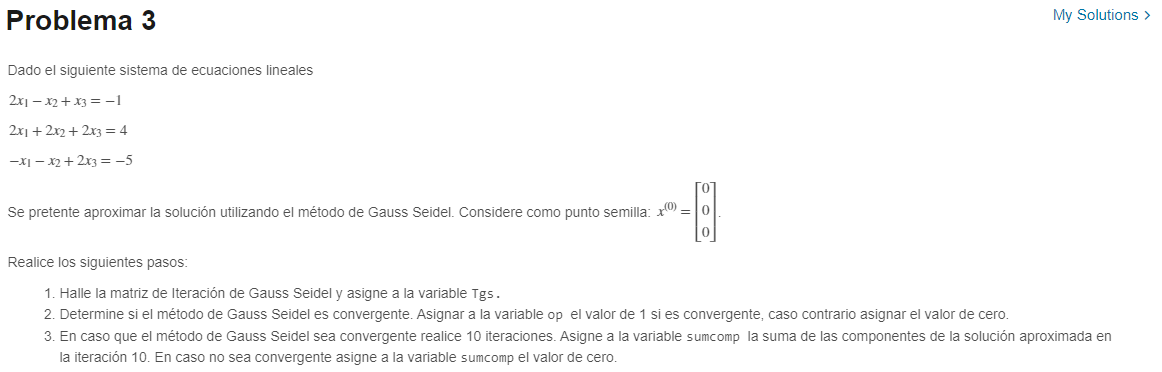

x0 = [0 0 0]'

x0 =      0
     0
     0


A = [2 -1 1; 2 2 2; -1 -1 2]

A =      2    -1     1
     2     2     2
    -1    -1     2


b = [-1 4 -5]'

b =     -1
     4
    -5



D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tgs=inv(D-L)*U

Tgs =                    0   0.500000000000000  -0.500000000000000
                   0  -0.500000000000000  -0.500000000000000
                   0                   0  -0.500000000000000



op = 0;
if max(eig(Tgs)) < 1
    op = 1;
end
op

op =      1



n = 10;
z = gausseidel_n(A,b,x0,n);
sumcomp = sum(z(end,1:end))

sumcomp =    2.002929687500000


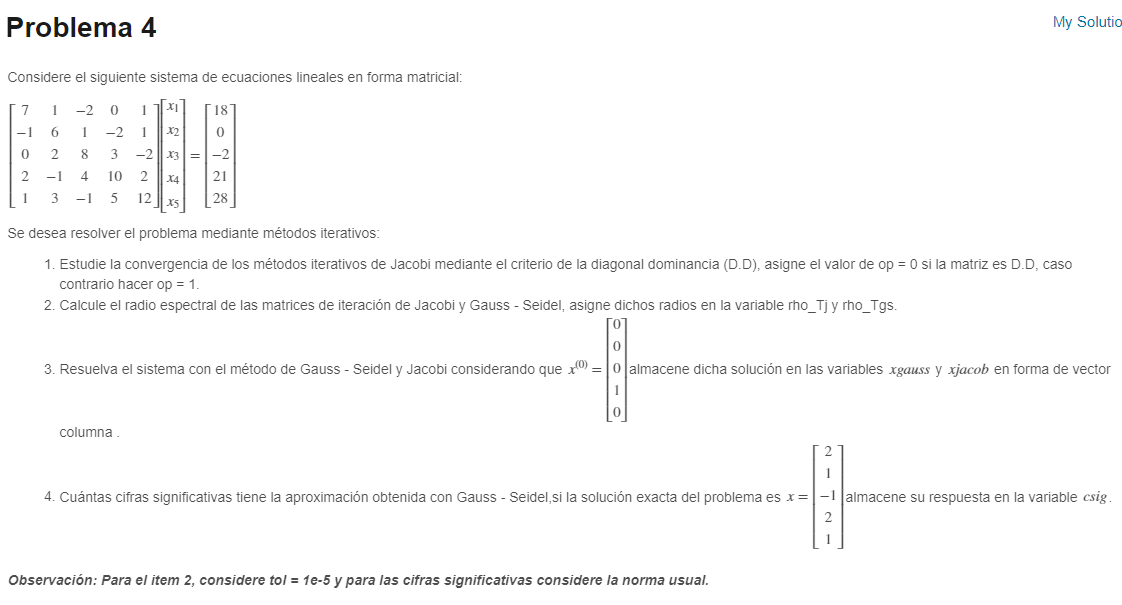

A = [7 1 -2 0 1
    -1 6 1 -2 1
    0 2 8 3 -2
    2 -1 4 10 2
    1 3 -1 5 12]

A =      7     1    -2     0     1
    -1     6     1    -2     1
     0     2     8     3    -2
     2    -1     4    10     2
     1     3    -1     5    12



b = [18 0 -2 21 28]'

b =     18
     0
    -2
    21
    28



op = 1

op =      1


if diagdom(A)
    op = 0
end

m =      5


n =      5


op =      0


op

op =      0


%--------------------------------
D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tj=inv(D)*(L+U);  
Tgs=inv(D-L)*U;  

rho_Tj=max(abs(eig(Tj)))  

rho_Tj =    0.753777717492837


rho_Tgs=max(abs(eig(Tgs)))  

rho_Tgs =    0.566297652292778




%-----------------------------------
tol = 1e-5; 

x0 = [0 0 0 1 0]';

xgauss = gausseidel(A,b,x0,tol);
xgauss = (xgauss(end,1:end-1))'

xgauss =    2.000011362917284
   0.999983201326279
  -0.999980086341345
   1.999983991502846
   1.000011582437359


xjacob = jacobi(A,b,x0,tol);
xjacob = (xjacob(end,1:end-1))'

xjacob =    2.000018924419924
   0.999960795756410
  -0.999947561966723
   1.999950216284808
   1.000044226667756



%-------------------------------------

x1 = [2 1 -1 2 1]';

err = norm(x1-xgauss, "inf")/norm(x1,"inf");
i = 0;

tope = 5*10^-i;
while err < tope
    i = i +1;
    tope = 5*10^-i;
end
csig = i-1

csig =      5


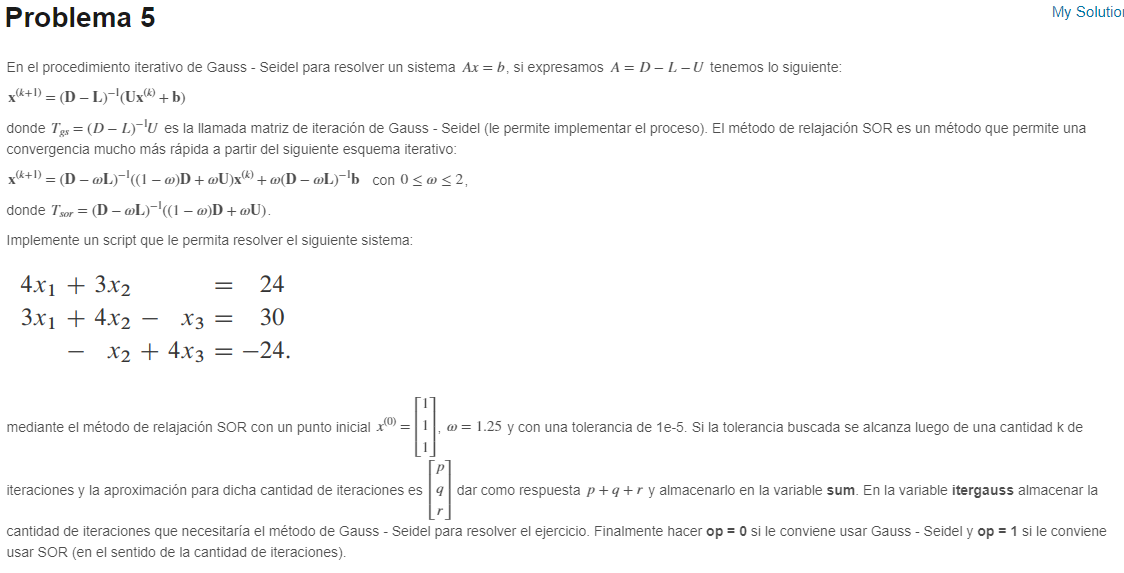

A = [4 3 0; 3 4 -1; 0 -1 4]

A =      4     3     0
     3     4    -1
     0    -1     4


b = [24;30;-24];

w = 1.25;
tol = 1e-5;

D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tsor=inv(D-L.*w)*(D.*(1-w) + w.*U);  
csor=inv(D-L.*w)*b*w;  
error=1;

x0 = [1 1 1]';
z=[x0'];  
i = 0;
while error>tol  
x1=Tsor*x0+csor;  
error=norm(x1-x0,inf)/norm(x1,inf);  
z=[z;x1'];  
x0=x1;  
i = i+1;
end

k = i;
a = z(end,1:end);
sum = sum(a)

sum =    1.999994905421294



% ---------------------------

x0 = [1 1 1]';
Tgs=inv(D-L)*U;  
cgs=inv(D-L)*b;  
error=1;  
z=[x0']; 
i = 0;
while error>tol
x1=Tgs*x0+cgs;  
error=norm(x1-x0,inf)/norm(x1,inf);  
z=[z;x1'];  
x0=x1;
i = i+1;
end  

itergauss = i

itergauss =     18



op = 1;
if itergauss < k
    op = 0;
end
op

op =      1


Norma P

function [z] = normaP(X)
s = 0;
p = 1.5;

X = abs(X);
X = X.^p;
s = sum(X);

z = s^(1/p);
end


Jacobi

function [z]=jacobi_1(A,b,x0,Tol)  
D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tj=inv(D)*(L+U);  
cj=inv(D)*b;  
error=1;  
i = 0;
z=[x0', i];  
while error>Tol  
x1=Tj*x0+cj;
i = i + 1;
error=normaP(x1-x0)/normaP(x1);  
z=[z;x1',i];  
x0=x1;  
end 
end 



function [z]=jacobi(A,b,x0,Tol)  
D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tj=inv(D)*(L+U);  
cj=inv(D)*b;  
error=1;  
z=[x0' error];  
while error>Tol  
x1=Tj*x0+cj;  
error=norm(x1-x0,inf)/norm(x1,inf);  
z=[z;x1' error];  
x0=x1;  
end  
end  

Gauss-Seidel

function [z]=gausseidel_n(A,b,x0,n)  
D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tgs=inv(D-L)*U;  
cgs=inv(D-L)*b;    
z=[x0'];
i = 0;
while n>i  
x1=Tgs*x0+cgs;    
z=[z;x1'];  
x0=x1;
i = i+1;
end  
end



function [z]=gausseidel(A,b,x0,Tol)  
D=diag(diag(A));  
L=-tril(A,-1);  
U=-triu(A,1);  
Tgs=inv(D-L)*U;  
cgs=inv(D-L)*b;  
error=1;  
z=[x0' error];  
while error>Tol  
x1=Tgs*x0+cgs;  
error=norm(x1-x0,inf)/norm(x1,inf);  
z=[z;x1' error];  
x0=x1;  
end  
end

Matriz Dominante

function op=diagdom(A)  
%op=1: diagonal estrictamente dominante  
%op=0: No es diagonal estrictamente dominante  
[m,n]=size(A)  
op=1;  
if m==n  
for k=1:m  
if abs(A(k,k)) < sum(abs(A(k,:)))-abs(A(k,k))  
op=0;  
break;  
end  
end  
end  
end